# 34763 Autonomous Marine Robotics - Training Session 2 - Learning models from data

## Get force body (Nm) as an input and forward velocity as an output from BAG file

% 

% Load ROS bag file
BAG_FILENAME = '_2024-02-27-15-54-51.bag';
bagselect = rosbag(BAG_FILENAME);

% Select messages related to pose ground truth
bSel_gt = select(bagselect, 'Topic', '/bluerov2/pose_gt');
msgStructs_gt = readMessages(bSel_gt, 'DataFormat', 'struct');
time_gt = bSel_gt.MessageList.Time;

u = cellfun(@(m) double(m.Twist.Twist.Linear.X), msgStructs_gt);

% Select messages related to thrust
[thrust0,time_thrust0] = thrust_parsing(bagselect,'/bluerov2/thrusters/0/thrust');
[thrust1,time_thrust1] = thrust_parsing(bagselect,'/bluerov2/thrusters/1/thrust');
[thrust2,time_thrust2] = thrust_parsing(bagselect,'/bluerov2/thrusters/2/thrust');
[thrust3,time_thrust3] = thrust_parsing(bagselect,'/bluerov2/thrusters/3/thrust');
[thrust4,time_thrust4] = thrust_parsing(bagselect,'/bluerov2/thrusters/4/thrust');
[thrust5,time_thrust5] = thrust_parsing(bagselect,'/bluerov2/thrusters/5/thrust');

d_X = 0.135;
d_Y = 0.115;
gamma = pi/4;
d_perp = d_X*sin(gamma)+d_Y*cos(gamma);

M = [cos(gamma) cos(gamma) -cos(gamma) -cos(gamma);
     sin(gamma) -sin(gamma) sin(gamma) -sin(gamma);
     d_perp     -d_perp     -d_perp    d_perp];

thrust03 = [thrust0, thrust1, thrust2, thrust3];
MF = M* thrust03';
Fx = MF(1,:);

% ==== Time synchronization ====

% Determine the minimum and maximum time values
t_start = max(time_thrust0(1), time_gt(1));
t_end = min(time_thrust0(end), time_gt(end));

% Determine the time step (delta)
delta_t1 = diff(time_thrust0(1:2)); % Time step for t1
delta_t2 = diff(time_gt(1:2)); % Time step for t2
delta_time = min(delta_t1, delta_t2); % Use the minimum time step

% Create the common time array
time = t_start:delta_time:t_end;

u_sync = interp1(time_gt, u, time);
Fx_sync = interp1(time_thrust0, Fx, time);

## Data for model learning

The dynamical model we will try to learn is the so-called first order Nomoto model


$$\dot{u} = \alpha u + \beta F_x$$


where $u$ is the forward velocity, $F_x$ is the forward force, and $(\alpha \, , \, \beta)$ are the parameters to be estimated.

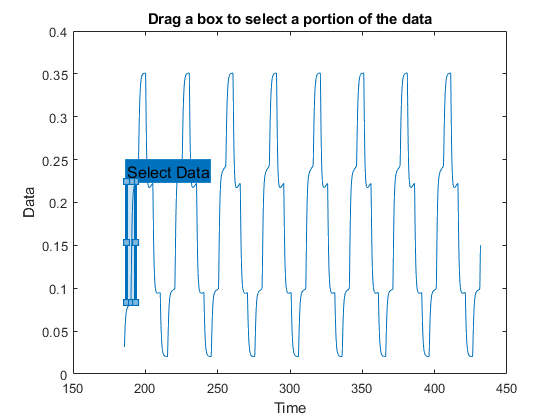

% Select portion of data for model identification (learning)

% Plot the entire time series
figure;
plot(time, u_sync);
title('Drag a box to select a portion of the data');
xlabel('Time');
ylabel('Data');

% Use drawrectangle to let the user select a portion of the data
rect = drawrectangle('Label','Select Data','Color',[0 0.4470 0.7410]);

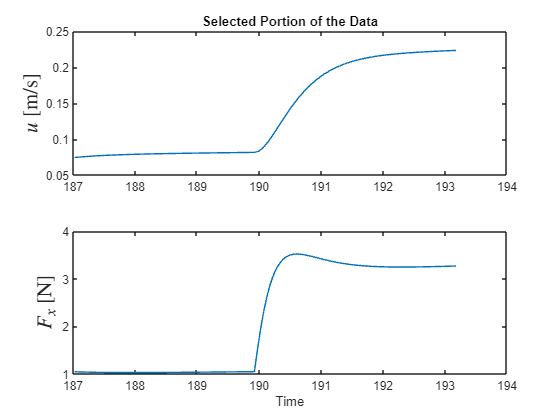

% Wait for the user to double-click the rectangle
wait(rect);

% Get the position of the rectangle
pos = rect.Position;

% Calculate the start and end time of the selected portion
startTime = pos(1);
endTime = startTime + pos(3);

% Find indices of the data points within the selected time range
selectedIndices = time >= startTime & time <= endTime;

% Extract the selected portion of the data
selectedTime = time(selectedIndices);
selectedData_out = u_sync(selectedIndices);
selectedData_inp = Fx_sync(selectedIndices);

% Plot the selected portion of the data in a new figure
figure; subplot(2,1,1)
plot(selectedTime, selectedData_out);
title('Selected Portion of the Data');
ylabel('$u$ [m/s]','FontSize',16,'FontName','Times','Interpreter','latex');
subplot(2,1,2), plot(selectedTime, selectedData_inp);
ylabel('$F_x$ [N]','FontSize',16,'FontName','Times','Interpreter','latex');
xlabel('Time');

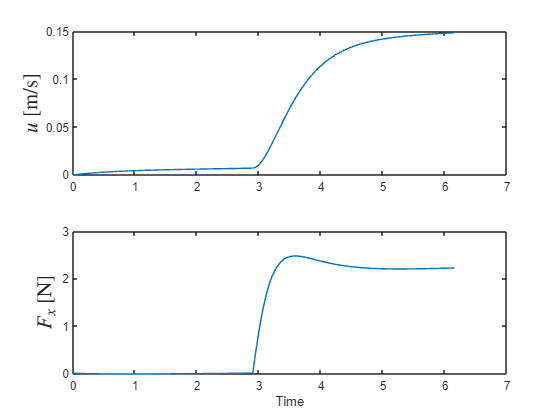

% remove the mean value of the first half second of data from both input
% and output data

u_ident = selectedData_out - mean(selectedData_out(1:4));
Fx_ident = selectedData_inp - mean(selectedData_inp(1:4));
time_ident = selectedTime - selectedTime(1);

figure; subplot(2,1,1)
plot(time_ident,u_ident);
ylabel('$u$ [m/s]','FontSize',16,'FontName','Times','Interpreter','latex');
subplot(2,1,2), plot(time_ident, Fx_ident);
ylabel('$F_x$ [N]','FontSize',16,'FontName','Times','Interpreter','latex');
xlabel('Time');

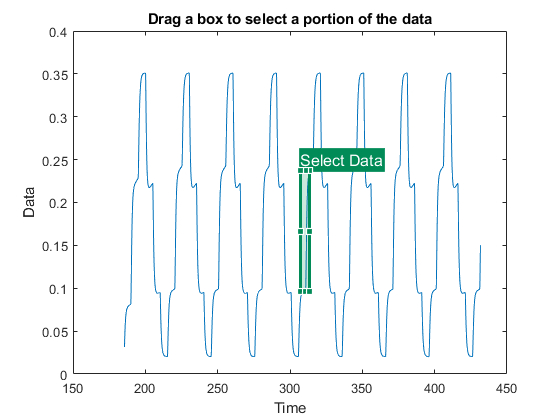

% Select portion of data for model validation (assessing)

% Plot the entire time series
figure;
plot(time, u_sync);
title('Drag a box to select a portion of the data');
xlabel('Time');
ylabel('Data');

% Use drawrectangle to let the user select a portion of the data
rect = drawrectangle('Label','Select Data','Color',[0 0.5470 0.3410]);

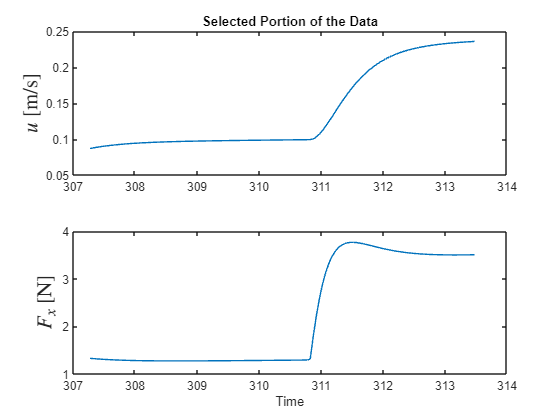


% Wait for the user to double-click the rectangle
wait(rect);

% Get the position of the rectangle
pos = rect.Position;

% Calculate the start and end time of the selected portion
startTime = pos(1);
endTime = startTime + pos(3);

% Find indices of the data points within the selected time range
selectedIndices = time >= startTime & time <= endTime;

% Extract the selected portion of the data
selectedTime = time(selectedIndices);
selectedData_out = u_sync(selectedIndices);
selectedData_inp = Fx_sync(selectedIndices);

% Plot the selected portion of the data in a new figure
figure; subplot(2,1,1)
plot(selectedTime, selectedData_out);
title('Selected Portion of the Data');
ylabel('$u$ [m/s]','FontSize',16,'FontName','Times','Interpreter','latex');
subplot(2,1,2), plot(selectedTime, selectedData_inp);
ylabel('$F_x$ [N]','FontSize',16,'FontName','Times','Interpreter','latex');
xlabel('Time');

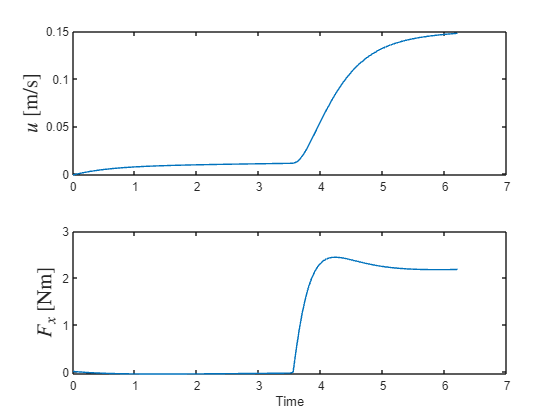


% remove the mean value of the first half second of data from both input
% and output data

u_valid = selectedData_out - mean(selectedData_out(1:4));
Fx_valid = selectedData_inp - mean(selectedData_inp(1:4));
time_valid = selectedTime - selectedTime(1);

figure; subplot(2,1,1)
plot(time_valid,u_valid);
ylabel('$u$ [m/s]','FontSize',16,'FontName','Times','Interpreter','latex');
subplot(2,1,2), plot(time_valid, Fx_valid);
ylabel('$F_x$ [Nm]','FontSize',16,'FontName','Times','Interpreter','latex');
xlabel('Time');

## Model learning

% Launch the system identification user interface
systemIdentification

% Inspect the learned model
present(ss1)

Unrecognized function or variable 'ss1'.